# Refinery Optimization

Refinery optimization deals with selecting the best way to process crude oil to maximize revenue, meet environmental regulations, meet customer contractual demands, and blend products or crude feed.

### Problem Statement

A refinery can use two different crude mixtures to produce gasoline, kerosine, fuel oil, and residual. The refinery has limits on daily production of each product, as well as different costs. The two crude sources have different costs, and efficiencies . producing each product shown in the table below:

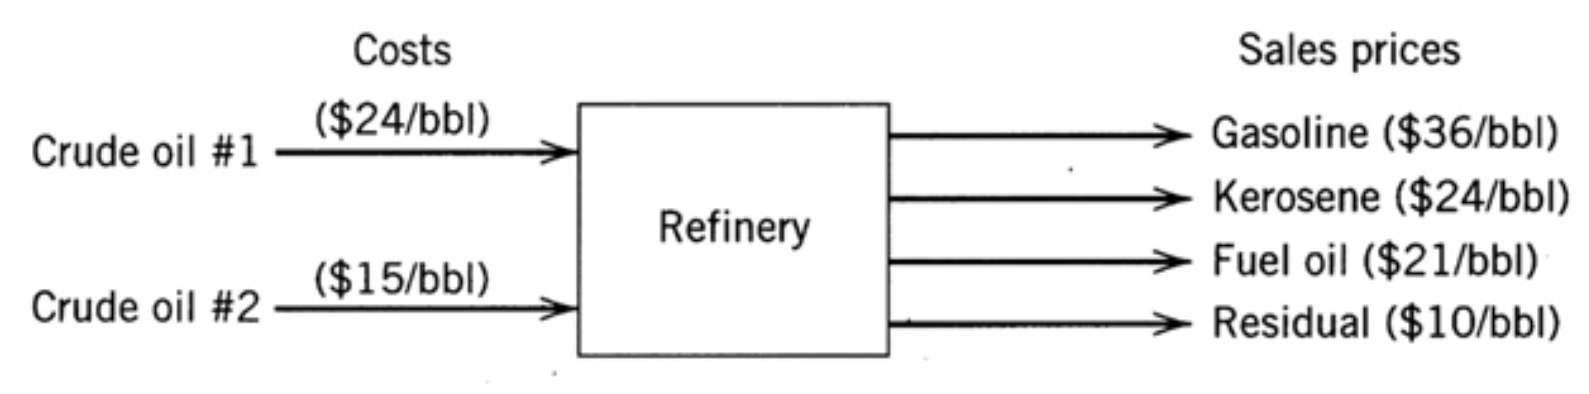

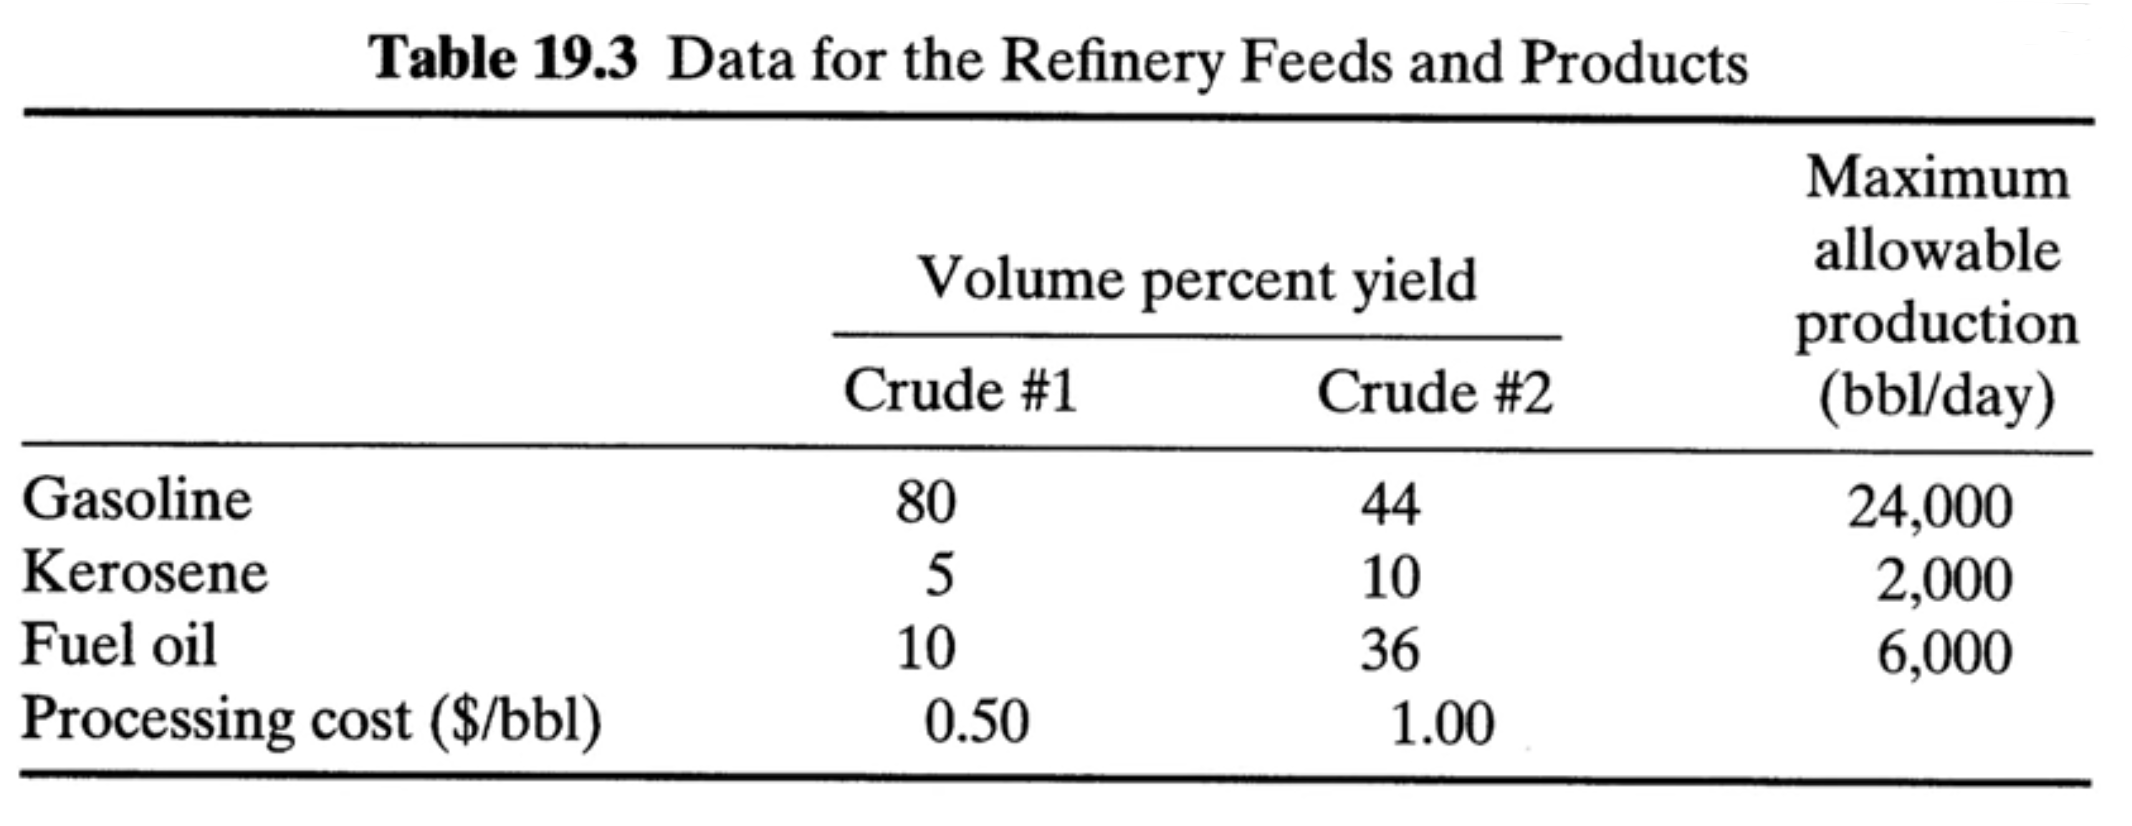

Profit will be determined in by the following equation:


$$\mathrm{Profit}=\mathrm{income}-\mathrm{raw\;material\;cost}-\mathrm{procedure\; cost}$$


Calculate the best allocation of production with the given constraints to maximize profit.

### Solution

Create variables

crude1 = optimvar('Crude1','LowerBound',0);
crude2 = optimvar('Crude2','LowerBound',0);
gasoline = optimvar('Gasoline','LowerBound',0,'UpperBound',24000);
kerosene = optimvar('Kerosene','LowerBound',0,'UpperBound',2000);
fuel_oil = optimvar('Fuel_Oil','LowerBound',0,'UpperBound',6000);
residual = optimvar('Residual','LowerBound',0);
income = optimvar('Income');
raw_mat_cost = optimvar('Raw_Material_Cost');
proc_cost = optimvar('Proc_Cost');
profit = optimvar('Profit');

Initialize Objective Function

linprob = optimproblem('ObjectiveSense',"maximize","Objective",profit);

linprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'maximize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.


Create Constraints

linprob.Constraints.econs1 = 0.8*crude1 + 0.44*crude2 == gasoline;
linprob.Constraints.econs2 = 0.05*crude1 + 0.1*crude2 == kerosene;
linprob.Constraints.econs3 = 0.1*crude1 + 0.36*crude2 == fuel_oil;
linprob.Constraints.econs4 = 0.05*crude1 + 0.1*crude2 == residual;

linprob.Constraints.econs5 = 36 * gasoline + 24 * kerosene + 21 * fuel_oil + 10 * residual == income;
linprob.Constraints.econs7 = 24*crude1 + 15*crude2 == raw_mat_cost;
linprob.Constraints.econs8 = 0.5*crude1 + crude2 == proc_cost;

linprob.Constraints.econs9 = income - raw_mat_cost - proc_cost == profit;

Solve

solution = solve(linprob)

Solving problem using linprog.

Optimal solution found.



solution = struct with fields:
               Crude1: 2.6207e+04
               Crude2: 6.8966e+03
             Fuel_Oil: 5.1034e+03
             Gasoline: 24000
               Income: 1.0392e+06
             Kerosene: 2.0000e+03
            Proc_Cost: 20000
               Profit: 2.8676e+05
    Raw_Material_Cost: 7.3241e+05
             Residual: 2.0000e+03
